# Επιστημονικός Υπολογισμός

## Εργαστηριακή Άσκηση 2022

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Στοιχεία Υπολογιστικού Συστήματος

Για να βρεθούν κάποιες από τις ζητούμενες πληροφορίες χρησιμοποιήθηκαν τα παρακάτω:

version('-blas')

ans = 'OpenBLAS 0.3.21'

version('-lapack')

ans = 'NAG Performance Components (NPC) Release 1.0.4, supporting Linear Algebra PACKage (LAPACK 3.9.1)'

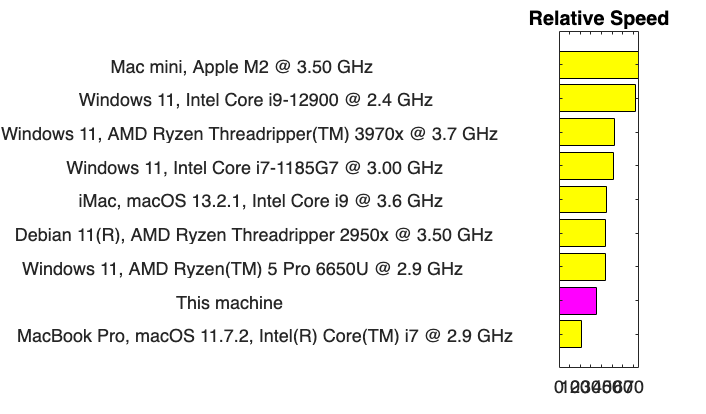

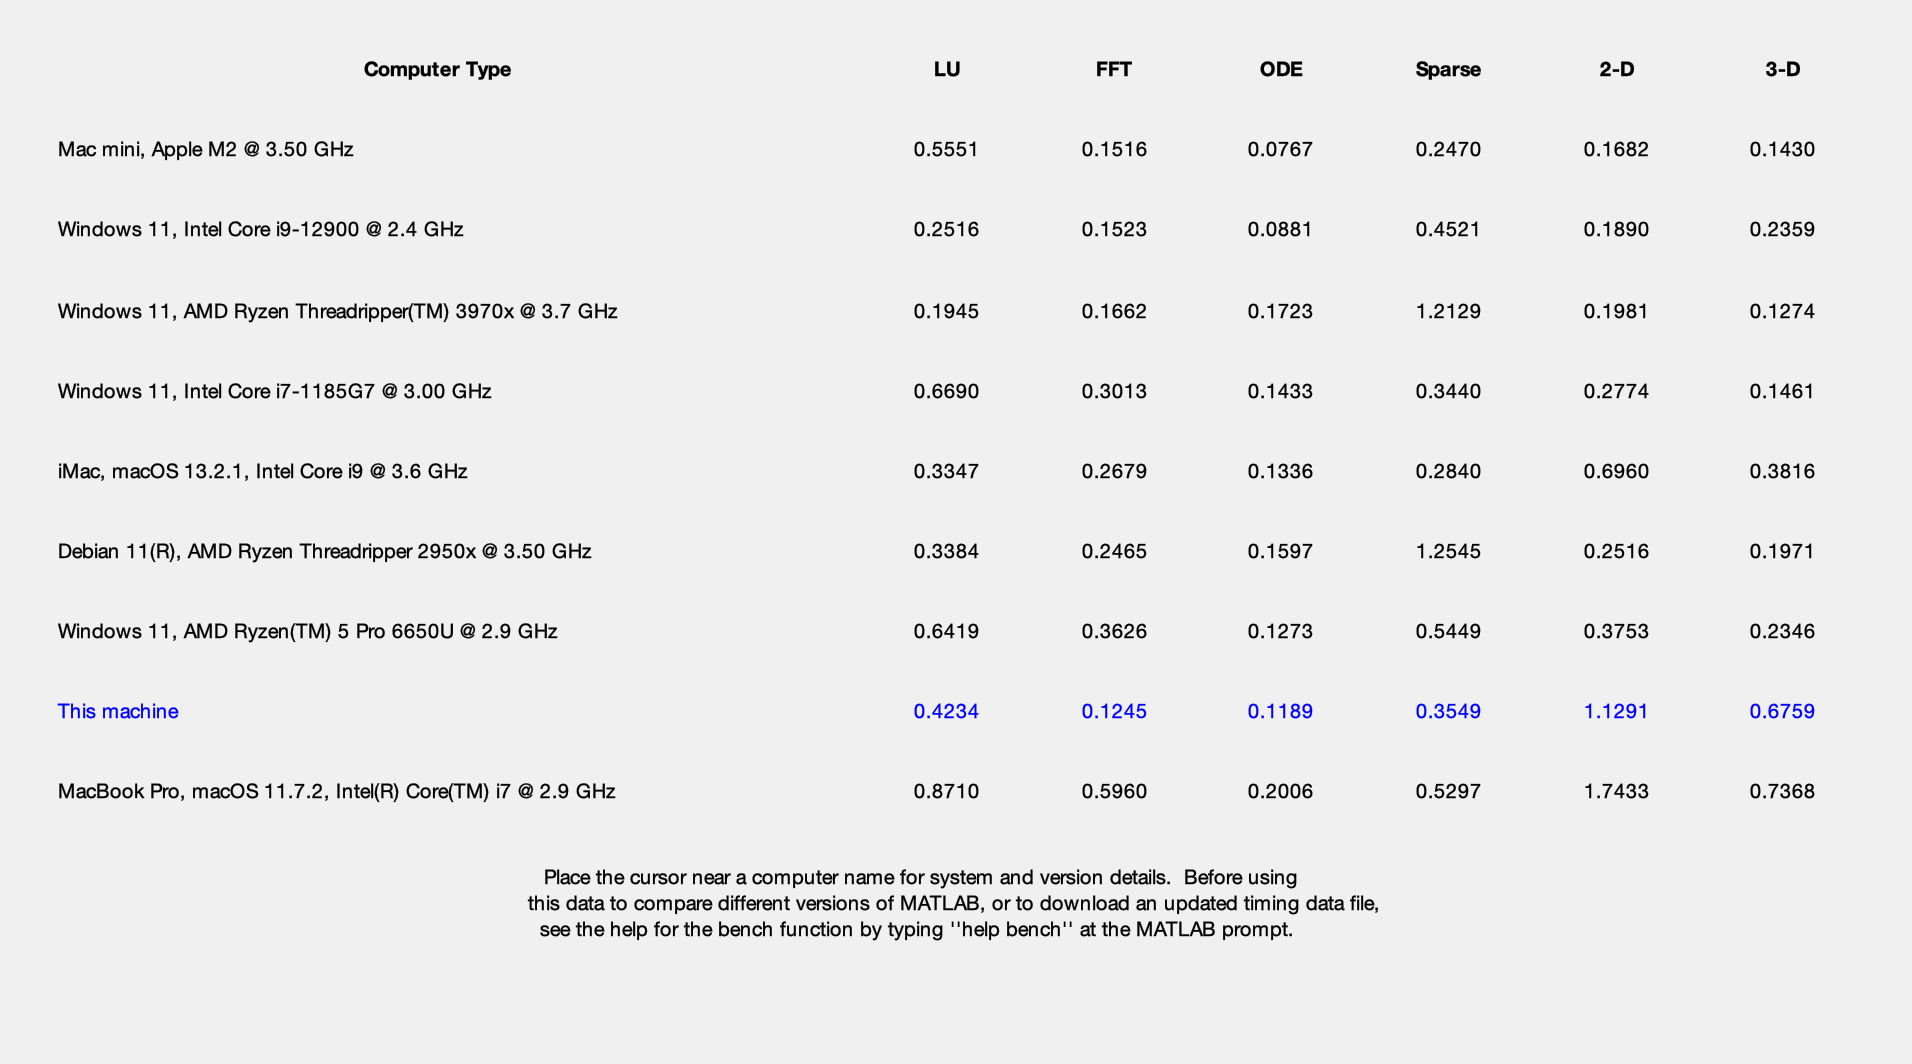

ans =     0.4234    0.1245    0.1189    0.3549    1.1291    0.6759


bench % (Μπαίνει σαν σχόλιο για να μην τρέξει αυτόματα)

## **Πράξεις με μητρώα ζώνης και λίγη θεωρία **

### Δομή αποθήκευσης μητρώων ζώνης:

#### Δεδομένα 

rng('default'); 
n=10; 
A=randi(10,n,n);
A=(A.*(abs([1:n]'-[1:n])<=2)).*(([1:n]'-[1:n])<=1)

A =      9     2     7     0     0     0     0     0     0     0
    10    10     1     1     0     0     0     0     0     0
     0    10     9     3     8     0     0     0     0     0
     0     0    10     1     8     2     0     0     0     0
     0     0     0     1     2     2     9     0     0     0
     0     0     0     0     5     5    10     4     0     0
     0     0     0     0     0    10     6     2     8     0
     0     0     0     0     0     0     2     3     8     5
     0     0     0     0     0     0     0     7     4     1
     0     0     0     0     0     0     0     0     6     4


T=A.*(abs([1:n]'-[1:n])<2);
D = diag(diag(T));
AL=-tril(T,-1);
AU=-triu(T,1);
C = A'; 
B = A+C;

#### Υλοποίηση

Δημιουργήθηκαν οι παρακάτω συναρτήσεις για μετατροπή μηρτώων από και προς την συμπιασμένη μορφή. 

`bandmatrix()`

([Άνοιγμα Ορισμού](matlab:open('./bandmatrix.m')))

Αυτή η συνάρτηση παίρνει ένα απλό διαγώνιο μητρώο και το συμπιέζει σύμφωνα με το [πρότυπο της LAPACK](https://netlib.org/lapack/lug_old/node113-.html).

`debandmatrix()`

([Άνοιγμα Ορισμού](matlab:open('./debandmatrix.m')))

Αυτή η συνάρτηση παίρνει ένα μητρώο το οποίο είναι συμπιεσμένο σύμφωνα με το [πρότυπο της LAPACK](https://netlib.org/lapack/lug_old/node113-.html) και το αποσυμπιέζει.

#### Παράδειγμα χρήσης

[AB,p,q] = bandmatrix(A)

Unrecognized function or variable 'bandmatrix'.

[A,p,q] = debandmatrix(AB)

#### Ζητούμενα

% Υπολογίζουμε τα παρακάτω
B2 = B*B
B2 = my_gbmm_1067400(B,B)

C2 = A*C
C2 = my_gbmm_1067400(A,C)

S=(D+AL+AU)*inv(D)*T
S= my_gbmm_1067400(my_gbmm_1067400((D+AL+AU),inv(D)), T)